%%Hydrological model. 
% Implement the hydrological model on the 6-year-long series of precipitation and discharge.
clear 
close

%% Load data
load area_rating_curve.txt
load kc.txt
load P.txt
load Q_obs.txt
load temperature.txt

Nyears_Q=length(Q_obs)/(365*24);
day_month=[31 28 31 30 31 30 31 31 30 31 30 31]; %"day_month": number of days for each month
month_end=cumsum(day_month);                     %"month_end": last day of each month
month_start=month_end-day_month+1;               %"month_start": first day of each month

%%Parameters for the hydrological model
sw = 0.25; %[-] Wilting point
s1 = 0.4; %[-] Soil moisture stress threshold
n = 0.3; %[-] Porosity
Q_b = 7; %[m^3/s] Baseflow
t_sup = 22; %[h] Mean superficial residence time
A = 4000; %[km^2] Catchment area
phi = 38; %[°] Latitude 

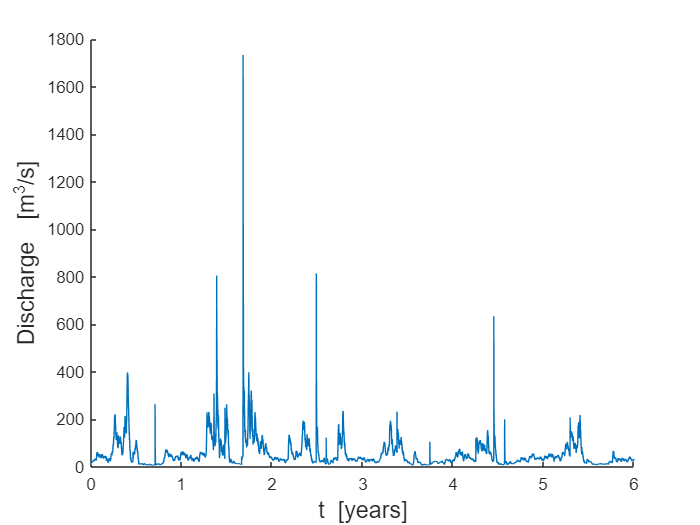

%% Plot discharge time series

figure(1)                                          %create a new figure
plot((1:length(Q_obs))/(365*24),Q_obs);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Discharge  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off 

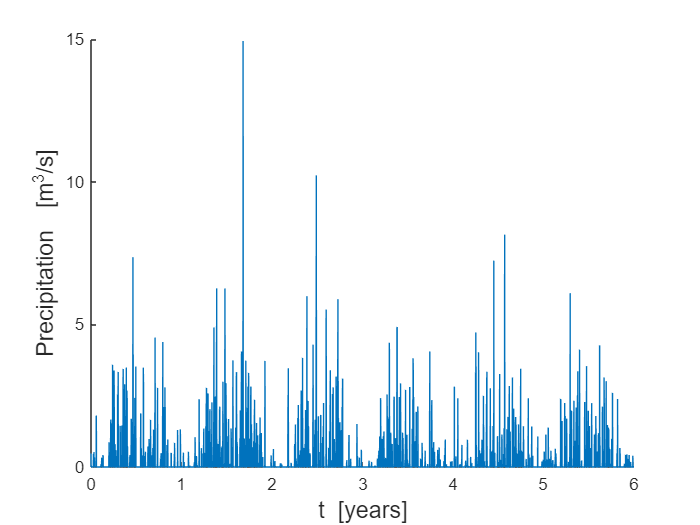


%% Plot precipitation time series

figure(2)                                          %create a new figure
plot((1:length(P))/(365*24),P);
xlabel('t  [years]','FONTSIZE',14)                 %insert label x axis
ylabel('Precipitation  [m^{3}/s]','FONTSIZE',14)       %insert label y axis
box off

%% 1.Compute reference crop evapotranspiration ET0 (potential evapotranspiration) 
% through the Thornthwaite equation 

I= sum((temperature./5).^(1.514)) ; %heat index
a= 6.75*(10^(-7))*(I^3) - 7.71*(10^(-5))*(I^2) + 1.79*(10^(-2))*I + 0.49; %experimental exponent
D = 1:365;
delta = 0.409*sin((2*pi*D/365)-1.39);
w_s = acos(-tan(phi)*tan(delta));
N_D = 24*w_s/pi; %number of daylight hours of day D
N_M =zeros(12,1); % mean daylight hours of month m

for i=1:12
    N_M(i) = sum((N_D(month_start(i):month_end(i))))/(day_month(i)); 
end

ET_0 = (16/12)*N_M.*((10*temperature/I).^a); % [mm/unit area]

%%2. Attribute arbitrary values to the parameters K_sat, c, t_sub, z.
% Hydrological model: to be calibrated

K_sat = 0; %[LT^(-1)] Hydraulic conductivity for saturated soil
c = 0; %[-] Exponent for power-law relation L(s)
z = 0; %[L] Root zone depth
t_sub = 0; %[T] Mean sub-superficial residence time
